# Assessment 2

H00368671

**Task1:**

% Part 1: Electric field at 1 nm from a 3 mC charge
Q = 3e-3; 
r = 1e-9; 
E = Efield(r, Q); 
fprintf('Electric field at %g m from a %g C charge is %g V/m\n', r, Q, E);

Electric field at 1e-09 m from a 0.003 C charge is 2.69632e+25 V/m


% Part 2: Weight on the surface of the sun
M_sun = 1.989e30;
R_sun = 695510e3;
m = 90; 
g = Gfield(R_sun, M_sun); 
F = m * abs(g); 
fprintf('Your weight on the surface of the sun is %g N\n', F);

Your weight on the surface of the sun is 24697.7 N


**Task 2:**

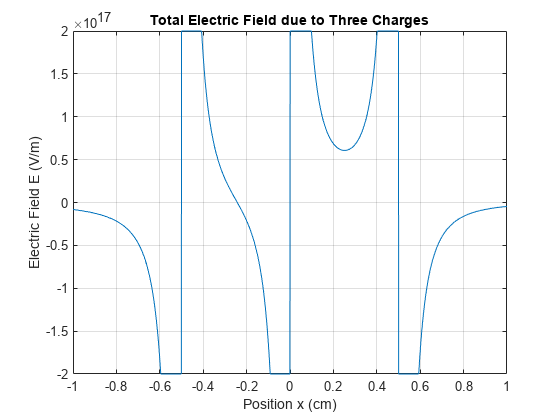

% Define charges and positions
Q1 = 20; 
Q2 = 20; 
Q3 = -20;

r1 = -0.005; 
r2 = 0;      
r3 = 0.005;  

% Define x range from -1 cm to 1 cm
x = linspace(-0.01, 0.01, 2000);

% Calculate electric fields due to each charge at all positions x
E1 = Efield(x - r1, Q1);
E2 = Efield(x - r2, Q2);
E3 = Efield(x - r3, Q3);

% Total electric field
E_total = E1 + E2 + E3;

% Truncate E_total to ±2e17 V/m
E_max = 2e17;
E_total(E_total > E_max) = E_max;
E_total(E_total < -E_max) = -E_max;

% Plot the total electric field
figure;
plot(x*100, E_total);
xlabel('Position x (cm)');
ylabel('Electric Field E (V/m)');
title('Total Electric Field due to Three Charges');
grid on;

**Task 3:**

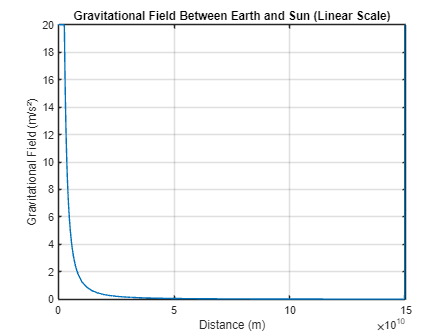

% Constants
G = 6.67e-11; 
M_sun = 1.989e30; 
M_earth = 5.972e24; 
distance_sun_earth = 149.6e9; 

% Create a vector of positions (x) from the Sun (x = 0) to the Earth (x = distance)
x = linspace(0, distance_sun_earth, 1e6); 

% Calculate gravitational field at each position
g_sun = G * M_sun ./ (x.^2); 
g_earth = G * M_earth ./ ((distance_sun_earth - x).^2); 

% Total gravitational field
g_total = g_sun + g_earth;

% Truncate the gravitational field to ±20 m/s²
g_total(g_total > 20) = 20;
g_total(g_total < -20) = -20;

% Plot the total gravitational field (linear scale on both axes)
figure;
plot(x, g_total);
xlabel('Distance (m)');
ylabel('Gravitational Field (m/s²)');
title('Gravitational Field Between Earth and Sun (Linear Scale)');
grid on;

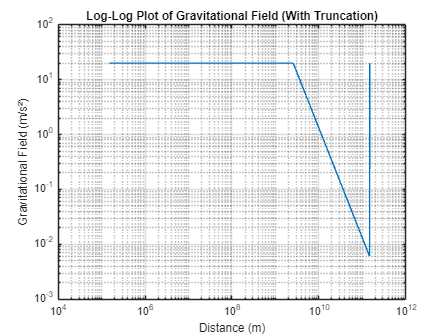


% Plot on log-log scale (with truncation)
figure;
loglog(x, abs(g_total));
xlabel('Distance (m)');
ylabel('Gravitational Field (m/s²)');
title('Log-Log Plot of Gravitational Field (With Truncation)');
grid on;

**Task 4:**

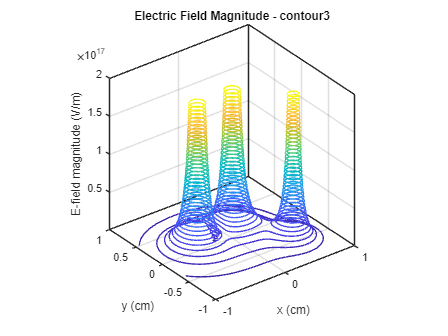

% Constants
epsilon0 = 8.854e-12; 
k = 1/(4*pi*epsilon0);

% Charges and positions
Q1 = -10; 
x1 = 0.005;  
y1 = -0.005; 

Q2 = 20;    
x2 = 0;    
y2 = 0;    

Q3 = 20;    
x3 = -0.005; 
y3 = 0;     

% Define grid
d = 0.01; 
dx = d/100;
X = -d:dx:d;
Y = -d:dx:d;
[X, Y] = meshgrid(X, Y); 

% Initialize total E-field components
Ex_total = zeros(size(X));
Ey_total = zeros(size(Y));

% Compute E-field due to Q1
r1 = sqrt((X - x1).^2 + (Y - y1).^2);
Ex1 = k * Q1 * (X - x1) ./ r1.^3;     
Ey1 = k * Q1 * (Y - y1) ./ r1.^3;

% Compute E-field due to Q2
r2 = sqrt((X - x2).^2 + (Y - y2).^2); 
Ex2 = k * Q2 * (X - x2) ./ r2.^3;     
Ey2 = k * Q2 * (Y - y2) ./ r2.^3;

% Compute E-field due to Q3
r3 = sqrt((X - x3).^2 + (Y - y3).^2); 
Ex3 = k * Q3 * (X - x3) ./ r3.^3;     
Ey3 = k * Q3 * (Y - y3) ./ r3.^3;

% Sum the components to get total E-field
Ex_total = Ex1 + Ex2 + Ex3;
Ey_total = Ey1 + Ey2 + Ey3;

% Compute magnitude of E-field
Emag = sqrt(Ex_total.^2 + Ey_total.^2);

% Truncate E-field values
E_max = 2e17;
Emag(Emag > E_max) = E_max;
Ex_total(Ex_total > E_max) = E_max;
Ey_total(Ey_total > E_max) = E_max;

% Plot using contour3
figure;
contour3(X*100, Y*100, Emag, 40)
xlabel('x (cm)')
ylabel('y (cm)')
zlabel('E-field magnitude (V/m)')
title('Electric Field Magnitude - contour3')
axis square

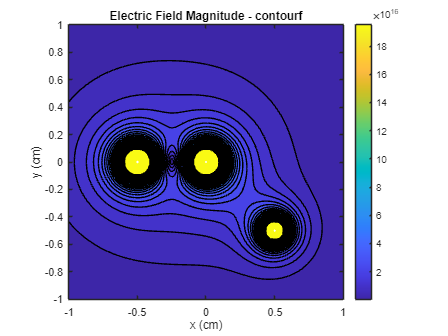


% Plot using contourf
figure;
contourf(X*100, Y*100, Emag, 40)
xlabel('x (cm)')
ylabel('y (cm)')
colorbar
title('Electric Field Magnitude - contourf')
axis square

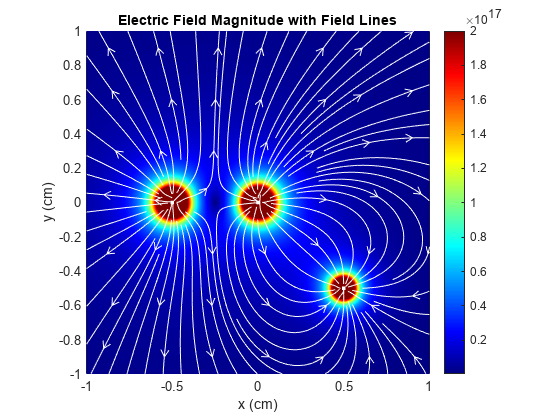


% Plot using pcolor + streamslice
figure;
pcolor(X*100, Y*100, Emag)
shading interp
colormap jet
colorbar
hold on
h = streamslice(X*100, Y*100, Ex_total, Ey_total);
set(h, 'Color', 'w')
xlabel('x (cm)')
ylabel('y (cm)')
title('Electric Field Magnitude with Field Lines')
axis square
box on

**Task 5:**

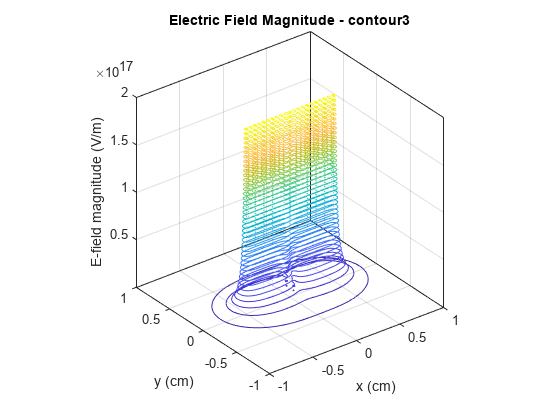

% Constants
epsilon0 = 8.854e-12; 
k = 1/(4*pi*epsilon0);

% Number of charges
N_charges = 21;

% Charges and positions
Q = ones(1, N_charges); 
Q((N_charges + 1)/2) = -1;

% Line orientation: horizontal line along x-axis
d = 0.01; 
x_positions = linspace(-d/2, d/2, N_charges);
y_positions = zeros(1, N_charges); % All charges lie along x-axis

% Define grid
grid_size = 0.02; 
dx = grid_size/200;
X = -grid_size/2:dx:grid_size/2;
Y = -grid_size/2:dx:grid_size/2;
[X, Y] = meshgrid(X, Y);

% Initialize total E-field components
Ex_total = zeros(size(X));
Ey_total = zeros(size(Y));

% Loop over each charge to compute its contribution
for i = 1:N_charges
    xi = x_positions(i);
    yi = y_positions(i);
    Qi = Q(i);
    
    % Compute E-field due to charge Qi
    r = sqrt((X - xi).^2 + (Y - yi).^2);
    Ex = k * Qi * (X - xi) ./ r.^3;
    Ey = k * Qi * (Y - yi) ./ r.^3;
    
    % Handle singularities (where r = 0)
    Ex(r == 0) = 0;
    Ey(r == 0) = 0;
    
    % Sum the components to get total E-field
    Ex_total = Ex_total + Ex;
    Ey_total = Ey_total + Ey;
end

% Compute magnitude of E-field
Emag = sqrt(Ex_total.^2 + Ey_total.^2);

% Truncate E-field values
E_max = 2e17;
Emag(Emag > E_max) = E_max;
Ex_total(Ex_total > E_max) = E_max;
Ey_total(Ey_total > E_max) = E_max;

% Plot using contour3
figure;
contour3(X*100, Y*100, Emag, 40)
xlabel('x (cm)')
ylabel('y (cm)')
zlabel('E-field magnitude (V/m)')
title('Electric Field Magnitude - contour3')
axis square

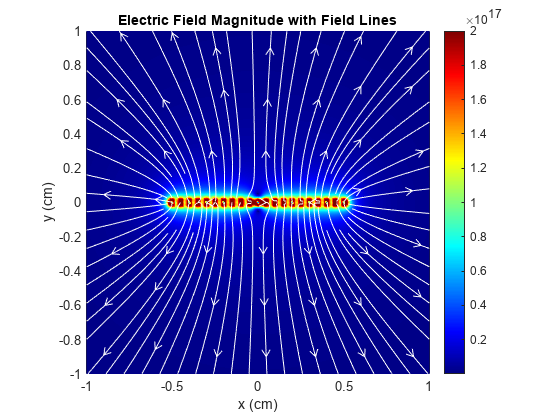


% Plot using contourf
figure;
contourf(X*100, Y*100, Emag, 40)
xlabel('x (cm)')
ylabel('y (cm)')
colorbar
title('Electric Field Magnitude - contourf')
axis square

% Plot using pcolor + streamslice
figure;
pcolor(X*100, Y*100, Emag)
shading interp
colormap jet
colorbar
hold on
h = streamslice(X*100, Y*100, Ex_total, Ey_total);
set(h, 'Color', 'w')
xlabel('x (cm)')
ylabel('y (cm)')
title('Electric Field Magnitude with Field Lines')
axis square
box on

**Functions:**

function E = Efield(r, Q)
epsilon0 = 8.854e-12; 
E = (1/(4*pi*epsilon0)) * Q ./ (abs(r).^2) .* (r./abs(r)); 
end

function g = Gfield(r, M)
G = 6.674e-11; 
g = -G * M ./ (abs(r).^2); 
end

